# Particles: Examples showing how to create and visualise particles

This examples demonstrates how to create and use different kinds of optical tweezers toolbox (OTT) particles.  For more information, see the corresponding example in the OTT documentat and the `particle` package reference section.  An interactive live script of this example is also available in the `examples/liveScripts/` directory.

% Add toolbox to path (uncomment this line if OTT is not already on the path)
%addpath('../');

## Creating a particle with simple geometry

OTT particles encapsulate the geometry, optical scattering and fluid drag information for a particle in an optical tweezers simulation. There are several ways to create particles, the simplest involve using the `FromShape` methods of the particle classes. These methods use the corresponding `FromShape` methods of the drag and T-matrix classes, however care should be taken when using large or complex particles, as these methods may not always give good approximations for the input geometry. The following create a shape and encapsulates it in a particle:

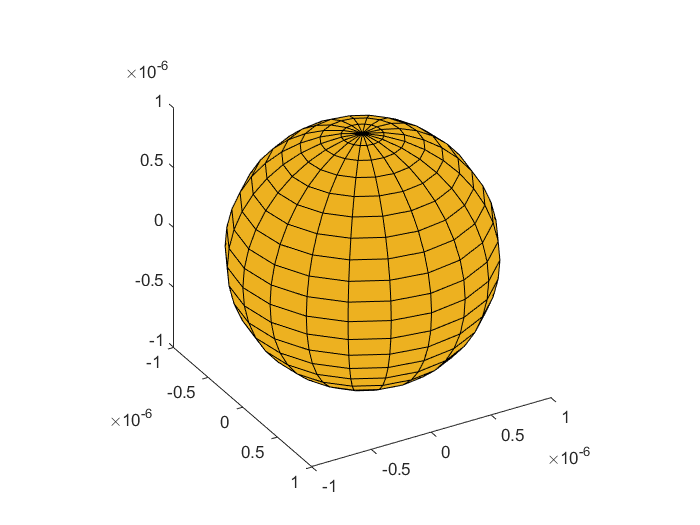

% Generate a geometric shape (units of meters)
shape = ott.shape.Sphere(1e-6);

% Create a particle
% For the T-matrix method, we need to specify relative index and wavelength
particle = ott.particle.Fixed.FromShape(shape, ...
  'index_relative', 1.2, 'wavelength0', 1064e-9);

% Show the shape geometry (via the particle)
figure();
particle.surf();


% Get the drag and tmatrix properties
particle.drag

ans =   StokesSphere with properties:

             radius: 1.0000e-06
    forwardInternal: [6×6 double]
            forward: [6×6 double]
            inverse: [6×6 double]
              gamma: [3×3 double]
              delta: [3×3 double]
         crossterms: [3×3 double]
             igamma: [3×3 double]
             idelta: [3×3 double]
        icrossterms: [3×3 double]
           rotation: [3×3 double]
    inverseInternal: [6×6 double]
          viscosity: 8.9000e-04


particle.tmatrix

ans =   Mie with properties:

                   radius: 0.9398
           index_relative: 1.2000
    relative_permeability: 1
                     type: 'scattered'
                     data: [336×336 double]
                     Nmax: [12 12]
                    total: [1×1 ott.tmatrix.Mie]
                scattered: [1×1 ott.tmatrix.Mie]


## Generate a particle with custom properties

Particle properties don't have to be related: this is useful when there is no avilable method for modelling the drag or scattering of a particle, or when we want to visualise the shape using a simpler geometry.

To create a particle with custom properties, we can use the `Fixed` sub-class. This class simply stores the provided properties.

For instance, we can create a particle instance with the geometry of a cylinder, T-matrix for a spheroid, and drag for a cylinder:

% Create geometry
wavelength = 1e-6;
shape = ott.shape.Cylinder(wavelength, wavelength);

% Create drag using FromShape
drag = ott.drag.Stokes.FromShape(shape, 'viscosity', 0.001);

% Create T-matrix for spheroid.
% There are several T-matrix methods included in the toolbox, Smarties
% works well for spheroidal particle.  This example creates a spheroid
% with similar dimensions to our Cylinder.  T-matrix methods use distance
% units with the dimensions of wavelength (particle/beams use meters).
index_relative = 1.2;
tmatrix = ott.tmatrix.Smarties(...
    shape.radius ./ wavelength, shape.height ./ wavelength, index_relative);

% Create particle instance
particle = ott.particle.Fixed(shape, 'drag', drag, 'tmatrix', tmatrix)

particle =   Fixed with properties:

         drag: [1×1 ott.drag.StokesLambNn]
      tmatrix: [1×1 ott.tmatrix.Smarties]
        shape: [1×1 ott.shape.Cylinder]
    tinternal: []
         mass: []
     position: [3×1 double]
     rotation: [3×3 double]


## Translations and rotations

Similar to beams, particles have `rotation` and `position` properties which can be used to control the position/rotation of the particle.

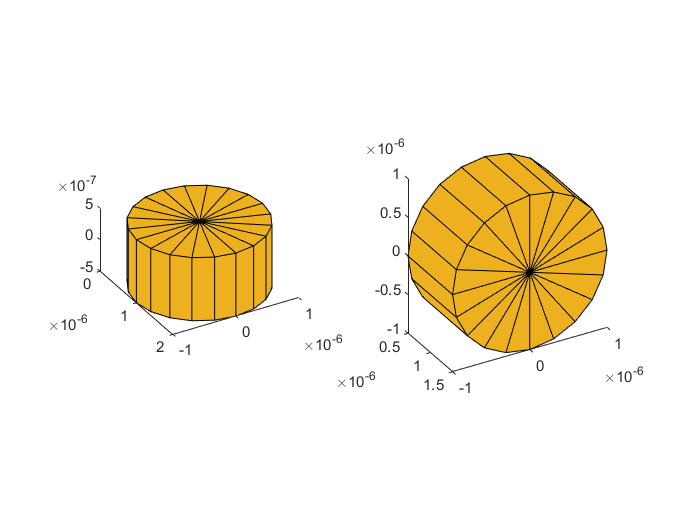

figure();

% Both rotation and position can be directly set, for example
subplot(1, 2, 1);
particle.position = [1;0;0]*wavelength;
particle.surf();

% And properties can be adjusted using the translate/rotate methods.
% As with beams, the rotate/translate methods return a copy of the object.
subplot(1, 2, 2);
rparticle = particle.rotateY(pi/2);
rparticle.surf();

## Calculating optical scattering

Particles can scatter beams (when there is an appropriate T-matrix definition).  For this example we setup a Gaussian beam and calculate the fields inside and outside a spherical particle.

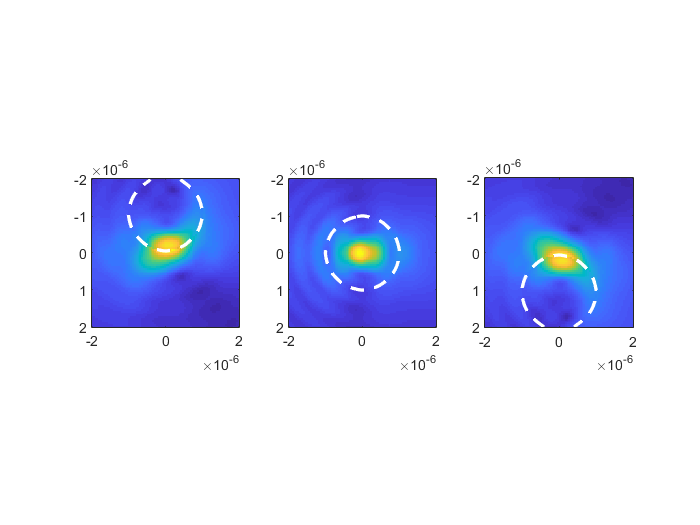

% Setup an incident beam
beam = ott.beam.Gaussian();

% Setup a particle
% Particle instance also support calculating internal fields for certain
% geometries (such as spherical particles).
shape = ott.shape.Sphere(1e-6);
particle = ott.particle.Fixed.FromShape(shape, ...
    'internal', true, 'index_relative', 1.2, ...
    'wavelength0', beam.wavelength0);
  
figure();
nlocs = 3;
xx = linspace(-1, 1, nlocs);

for ii = 1:nlocs
    
  subplot(1, nlocs, ii);
  x = xx(ii);
  
  % Calcualate scattering
  sbeam = beam.scatter(particle, 'position', [x;0;0]*beam.wavelength);
  
  % The scattered beam stores an instance of the particle and the incident
  % beam, allowing us to easily visualise the internal and external fields.
  sbeam.visNearfield('axis', 'y', 'range', [1,1]*2e-6);
  
end

## Calculating force

Force can be calculated either directly using the `force` method of the scattered beam or using the `force` method of the incident beam:

% With the scattered beam
% The resulting force has units of newtons.
force = sbeam.force()

force = 	1.0e+-8 *

    0.1383
   -0.0139
   -0.0612



% With the incident beam we can specify a range of positions.
% These positions are applied on top of any existing particle positions.
positions = randn(3, 5)*1e-6;
forces = beam.force(particle, 'position', positions)

forces = 	1.0e+-8 *

   -0.0054    0.0025   -0.1284    0.0007   -0.0341
   -0.0887    0.0855    0.0332    0.0158   -0.0466
   -0.0399   -0.0337   -0.0546   -0.0013    0.0013


## About

This example live script is part of OTT.  Written by Isaac Lenton.  For further details see [https://github.com/ilent2/ott](https://github.com/ilent2/ott)